The code gives output of energy diagram at given max charging ppower:

% 1. Data Import
% Read the net produce file you generated earlier
net_data = readtable('Team38_net_produce.csv');

% Extract time and net power directly
time_s = net_data{:, 1}; 
P_net = net_data{:, 2}; % This is ALREADY Supply - Demand

% Convert time to hours
time_h = time_s / 3600;

% 2. Calculate Storage Power (Allowing for Discharging)
max_charge_power = 300;    % Max power going INTO storage
max_discharge_power = 100; % Max power coming OUT OF storage

% If P_net is positive, it charges (capped at +200)
% If P_net is negative, it discharges (capped at -200)
P_storage_power = max(min(P_net, max_charge_power), -max_discharge_power);

% 3. Calculate Cumulative Energy via Integration
cumulative_net_energy = cumtrapz(time_h, P_net);           % Total theoretical net energy
energy_storage_level = cumtrapz(time_h, P_storage_power);  % Actual energy in the storage system
max(energy_storage_level)

ans = 6.6203e+04

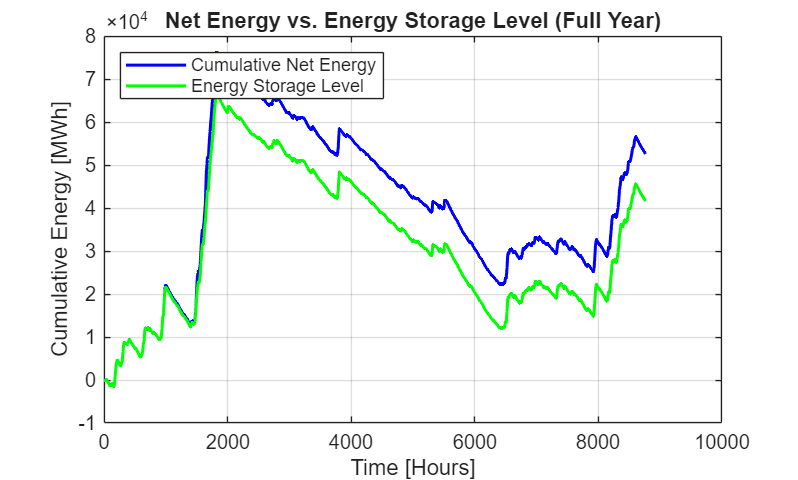

% --- 4. Plotting ---

% Figure 1: Cumulative Energy Comparison Plot
figure;
plot(time_h, cumulative_net_energy, 'b-', 'LineWidth', 1.5); hold on;
plot(time_h, energy_storage_level, 'g-', 'LineWidth', 1.5);
title('Net Energy vs. Energy Storage Level (Full Year)');
xlabel('Time [Hours]');
ylabel('Cumulative Energy [MWh]');
legend('Cumulative Net Energy', 'Energy Storage Level', 'Location', 'northwest');
grid on;

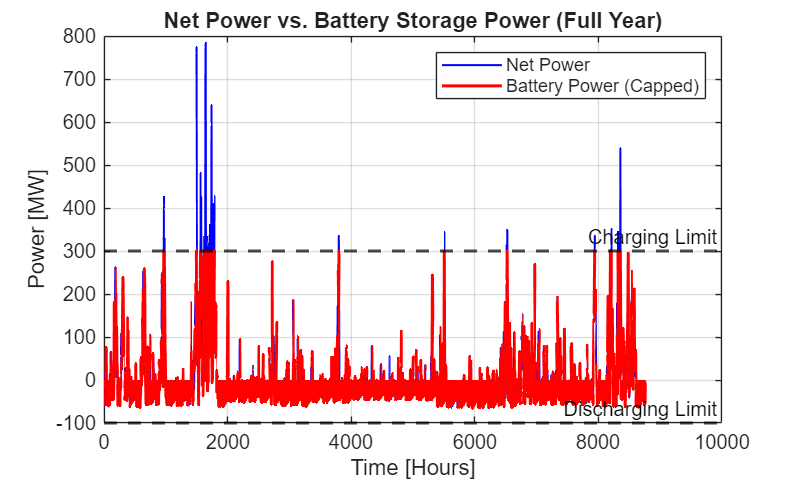


% Figure 2: Power Comparison Plot (Full Year)
figure;
plot(time_h, P_net, 'b-', 'LineWidth', 1); hold on;
plot(time_h, P_storage_power, 'r-', 'LineWidth', 1.5);
yline(max_charge_power, 'k--', 'Charging Limit', 'LineWidth', 1.5);
yline(-max_discharge_power, 'k--', 'Discharging Limit', 'LineWidth', 1.5);

title('Net Power vs. Battery Storage Power (Full Year)');
xlabel('Time [Hours]');
ylabel('Power [MW]');
legend('Net Power', 'Battery Power (Capped)');
grid on;

this one gives the efficiency to max charging power:

methology documentation (generated by AI):

1. Defining the Surplus

First, we take your Net Produce ($P_{net} = Supply - Demand$) and zero out any negative values, because you can only charge the system when there is a surplus: 

$$P_{surplus}(t) = \max(P_{net}(t), 0)$$

2. Total Available Energy

We calculate the absolute maximum energy you could store if you had an infinite charging capacity. This is done by integrating the surplus power over the entire year using the trapezoidal rule (`trapz` in MATLAB): $$E_{total} = \int P_{surplus}(t) , dt$$

3. Simulating the Charging Limit (Clipping)

For a given maximum charging power ($P_{max}$), we "clip" the surplus curve. The battery charges at the surplus power *unless* the surplus exceeds $P_{max}$: $$P_{charge}(t) = \min(P_{surplus}(t), P_{max})$$

We then integrate this clipped curve to find the **Actual Stored Energy** for that specific limit: $$E_{stored}(P_{max}) = \int P_{charge}(t) , dt$$ *The code runs this calculation in a loop for 200 different values of $P_{max}$ (from 10 to 500 MW).*4. Calculating the Metrics

With the integrals solved, the math for the two plots is simply:

- **Capture Efficiency** (Plot 1): What fraction of the total surplus did we catch? $$\eta_{capture} = \frac{E_{stored}(P_{max})}{E_{total}} \times 100%$$

- **Marginal Gain** (Plot 2): How does the stored energy change when we increase the power limit? We calculate this using the discrete numerical derivative (`gradient` in MATLAB): $$\text{Marginal Gain} = \frac{d(E_{stored})}{d(P_{max})}$$ *(Units: MWh gained per MW added)*

data = readtable('Team38_net_produce.csv');
time_s  = data{:, 1};          % Time in seconds
P_net   = data{:, 2};          % Net produce in MW (supply - demand)
time_h  = time_s / 3600;       % Convert to hours for energy in MWh
dt_h    = diff(time_h);        % Time step sizes in hours

%% 2. Identify Surplus Power (positive net produce only)
P_surplus = max(P_net, 0);     % Zero out negative (deficit) periods

% Total available surplus energy over the year (MWh)
E_surplus_total = trapz(time_h, P_surplus);
fprintf('Total available surplus energy: %.2f MWh\n', E_surplus_total);

Total available surplus energy: 192237.13 MWh



% Peak surplus power
P_surplus_peak = max(P_surplus);
fprintf('Peak surplus power: %.2f MW\n', P_surplus_peak);

Peak surplus power: 784.69 MW



%% 3. Sweep over a range of max charging powers
P_max_range = linspace(10, 500, 200);  % 200 points from 10 to 500 MW

% Pre-allocate results
E_stored      = zeros(size(P_max_range));  % Total stored energy [MWh]
E_curtailed   = zeros(size(P_max_range));  % Curtailed energy [MWh]
eta_capture   = zeros(size(P_max_range));  % Capture efficiency [%]
util_factor   = zeros(size(P_max_range));  % Utilization factor [%]

total_hours = (time_s(end) - time_s(1)) / 3600;  % Total simulation hours

for i = 1:length(P_max_range)
    P_max_i = P_max_range(i);
    
    % Clip surplus to max charging power
    P_charge_i = min(P_surplus, P_max_i);
    
    % Integrate to get total stored energy
    E_stored(i) = trapz(time_h, P_charge_i);
    
    % Curtailed = what was available but couldn't be captured
    E_curtailed(i) = E_surplus_total - E_stored(i);
    
    % Capture efficiency: fraction of surplus actually stored
    eta_capture(i) = (E_stored(i) / E_surplus_total) * 100;
    
    % Utilization factor: how much of the max theoretical throughput is used
    util_factor(i) = (E_stored(i) / (P_max_i * total_hours)) * 100;
end

%% 4. Marginal Gain: additional MWh per additional MW of capacity
% dE_stored / dP_max  (units: MWh/MW = hours)
marginal_gain = gradient(E_stored, P_max_range);

%% 5. Find the "Knee" Point (90% capture efficiency)
target_efficiency = 90;  % percent
idx_knee = find(eta_capture >= target_efficiency, 1, 'first');
if ~isempty(idx_knee)
    P_knee = P_max_range(idx_knee);
    fprintf('\n--- Knee Point (%.0f%% capture) ---\n', target_efficiency);
    fprintf('Required max charging power: %.1f MW\n', P_knee);
    fprintf('Energy stored: %.2f MWh\n', E_stored(idx_knee));
    fprintf('Curtailed energy: %.2f MWh\n', E_curtailed(idx_knee));
else
    P_knee = NaN;
    fprintf('\n%.0f%% capture not reached in the tested range.\n', target_efficiency);
end


--- Knee Point (90% capture) ---


Required max charging power: 239.0 MW


Energy stored: 173058.05 MWh


Curtailed energy: 19179.07 MWh


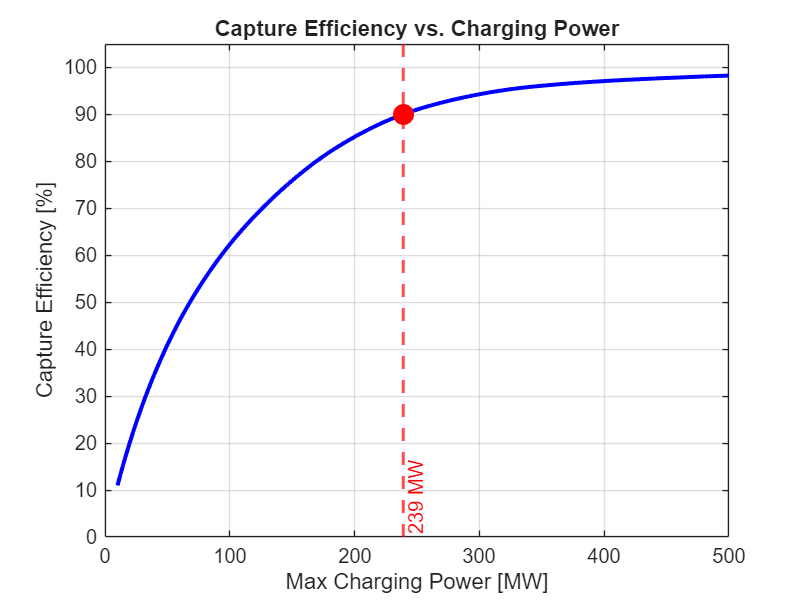


%% 6. Plotting

% --- Figure 1: Capture Efficiency ---
figure('Position', [100, 100, 800, 600], 'Color', 'w');
plot(P_max_range, eta_capture, 'b-', 'LineWidth', 2);
hold on;
if ~isnan(P_knee)
    xline(P_knee, 'r--', sprintf('%.0f MW', P_knee), ...
        'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right', ...
        'LabelVerticalAlignment', 'bottom');
    plot(P_knee, eta_capture(idx_knee), 'ro', 'MarkerSize', 10, ...
        'MarkerFaceColor', 'r');
end
xlabel('Max Charging Power [MW]');
ylabel('Capture Efficiency [%]');
title('Capture Efficiency vs. Charging Power');
grid on;
ylim([0 105]);

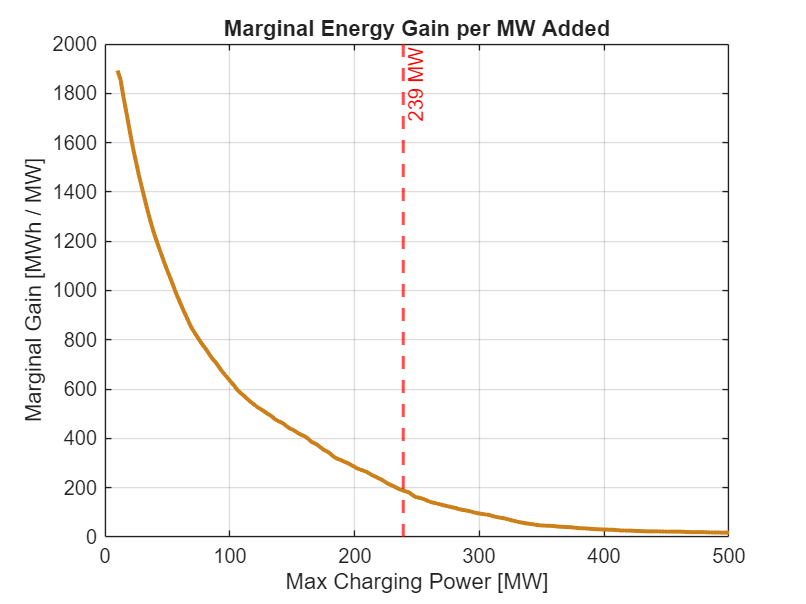


% --- Figure 2: Marginal Gain ---
figure('Position', [150, 150, 800, 600], 'Color', 'w');
plot(P_max_range, marginal_gain, 'Color', [0.8 0.5 0.1], 'LineWidth', 2);
hold on;
if ~isnan(P_knee)
    xline(P_knee, 'r--', sprintf('%.0f MW', P_knee), ...
        'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right');
end
xlabel('Max Charging Power [MW]');
ylabel('Marginal Gain [MWh / MW]');
title('Marginal Energy Gain per MW Added');
grid on;


%% 7. Summary Table
fprintf('\n============ Summary Table ============\n');


============ Summary Table ============


fprintf('%-12s  %-12s  %-12s  %-12s  %-14s\n', ...
    'P_max [MW]', 'E_stored', 'E_curt', 'Capture[%]', 'Util[%]');

P_max [MW]    E_stored      E_curt        Capture[%]    Util[%]       


fprintf('%-12s  %-12s  %-12s  %-12s  %-14s\n', ...
    '', '[GWh]', '[GWh]', '', '');

              [GWh]         [GWh]                                     


fprintf('%s\n', repmat('-', 1, 68));

--------------------------------------------------------------------



% Print at selected power levels
P_print = [25, 50, 100, 150, 200, 250, 300, 400, 500];
for p = P_print
    [~, idx] = min(abs(P_max_range - p));
    fprintf('%-12.0f  %-12.2f  %-12.2f  %-12.1f  %-14.1f\n', ...
        P_max_range(idx), E_stored(idx)/1e3, E_curtailed(idx)/1e3, ...
        eta_capture(idx), util_factor(idx));
end

25            46.46         145.78        24.2          21.4          
49            78.03         114.20        40.6          18.0          
101           120.51        71.72         62.7          13.6          
150           146.11        46.13         76.0          11.1          
200           163.72        28.52         85.2          9.4           
249           174.81        17.43         90.9          8.0           
301           181.32        10.91         94.3          6.9           
399           186.64        5.60          97.1          5.3           
500           188.92        3.31          98.3          4.3           


fprintf('%s\n', repmat('=', 1, 68));

## Optimal Volume analysis

## Mathmatical approach documentation

## 1. Establishing the Realistic Baseline

Before sizing the volume, we must recognize that the system already has a charging power limit (e.g., 300 MW).

- **Calculate Raw Surplus:** $$P_{surplus}(t) = \max(Supply(t) - Demand(t), 0)$$

- **Apply Power Limit:** Any surplus above 300 MW is physically rejected by the compressor. Thus, the actual "storable" power is: $$P_{capped}(t) = \min(P_{surplus}(t), 300)$$

- **Total Available Energy:** The baseline for 100% efficiency is the total energy that makes it past the compressor over the year: $$E_{total_storable} = \int P_{capped}(t) dt$$

*(This prevents penalizing the storage volume for energy that the compressor was too slow to capture).*2. Converting Energy to CAES Volume

The required physical volume (in $m^3$) of compressed air is calculated using the work equation for ideal isothermal expansion:

$$E = P_{store} \cdot V \cdot \ln\left(\frac{P_{store}}{P_{atm}}\right)$$

Where:

- $E$ = Stored Energy (Joules)

- $P_{store}$ = Storage Pressure ($80 \times 10^5$ Pa)

- $P_{atm}$ = Atmospheric Pressure ($101325$ Pa)

- $V$ = Volume ($m^3$)

**Rearranging to solve for Volume:** $$V = \frac{E}{P_{store} \cdot \ln\left(\frac{P_{store}}{P_{atm}}\right)}$$

The code uses this formula to create a direct conversion factor, allowing us to map electrical capacity (MWh) directly to cavern size ($m^3$).

## 3. The Time-Domain Simulation (State Tracking)

Unlike analyzing power limits, analyzing volume limits requires a step-by-step simulation because the tank has a state (how full it is).

For a given maximum tank capacity ($V_{max}$), we track the State of Charge ($SOC$) at every 15-minute timestep ($\Delta t$):

During a Surplus (Charging):

The energy we *want* to store is: $$E_{available} = P_{capped}(t) \times \Delta t$$

The empty space left in the tank is: $$E_{room} = V_{max} - SOC(t)$$

The energy we *actually* store is bounded by whichever is smaller: $$E_{actual} = \min(E_{available}, E_{room})$$

We then update the tank level: $$SOC(t+1) = SOC(t) + E_{actual}$$

*(Any energy $E_{available}$ that exceeds $E_{room}$ is counted as curtailed/wasted).*

During a Deficit (Discharging):

When demand exceeds supply, we empty the tank to compensate, opening up room for future surplus: $$SOC(t+1) = SOC(t) - E_{discharged}$$

## 4. Calculating the Final Metrics

After running the year-long simulation across many hypothetical tank sizes, we calculate:

- **Capture Efficiency:** $$\eta = \frac{\sum E_{actual}}{E_{total_storable}} \times 100%$$ *What percentage of the energy that passed the compressor successfully fit inside the tank?*

- **Marginal Gain:** $$\frac{\Delta E_{captured}}{\Delta V_{max}}$$ *How many extra MWh do we capture over the year if we dig exactly 1 more cubic meter of cavern space?*

data = readtable('Team38_net_produce.csv');
time_s = data{:, 1};          % Time in seconds
P_net  = data{:, 2};          % Net produce in MW (supply - demand)
time_h = time_s / 3600;       % Convert to hours
N      = length(P_net);       % Number of data points

% Time step (constant at 900s = 0.25 hours)
dt_h = 900 / 3600;  % 0.25 hours

%% 2. Configuration
% Fix the max charging power to a realistic value
P_charge_max = 300;    % [MW] max charging power limit
P_discharge_max = Inf; % [MW] no discharging rate limit

%% 3. Identify Surplus and Deficit
P_surplus_raw = max(P_net, 0);    % Positive part: available for charging
P_deficit = min(P_net, 0);        % Negative part: demand exceeds supply

% The supply energy is reduced because of the charging power limit.
% So the "available" energy for storage is ONLY what gets past the charger.
P_surplus_capped = min(P_surplus_raw, P_charge_max);

% Total available surplus energy AFTER the power constraint
E_surplus_total = trapz(time_h, P_surplus_capped);
fprintf('Total surplus energy (after %g MW cap): %.2f MWh\n', P_charge_max, E_surplus_total);

Total surplus energy (after 300 MW cap): 181270.07 MWh


fprintf('Peak surplus power (capped): %.2f MW\n', max(P_surplus_capped));

Peak surplus power (capped): 300.00 MW



% CAES (Compressed Air Energy Storage) conversion parameters
% Formula:  E = P_store * V * ln(P_store / P_atm)
% Solved:   V = E / (P_store * ln(P_store / P_atm))
P_store = 80e5;       % Storage pressure [Pa] (80 bar)
P_atm   = 101325;     % Atmospheric pressure [Pa] (1 atm)
T_store = 300;        % Storage temperature [K]

% Energy-to-volume conversion factor: MWh -> m^3
% 1 MWh = 3.6e9 J
J_per_MWh = 3.6e9;
E_density = P_store * log(P_store / P_atm);  % [J/m^3]
MWh_to_m3 = J_per_MWh / E_density;           % [m^3 per MWh]
fprintf('CAES energy density: %.2f MJ/m^3\n', E_density / 1e6);

CAES energy density: 34.95 MJ/m^3


fprintf('Conversion factor: 1 MWh = %.2f m^3 of compressed air\n', MWh_to_m3);

Conversion factor: 1 MWh = 103.00 m^3 of compressed air



%% 4. Sweep over a range of max storage volumes
V_max_range = linspace(100, 70000, 200);  % 200 points from 100 to 50000 MWh

% Pre-allocate results
E_captured    = zeros(size(V_max_range));  % Total energy captured [MWh]
E_curtailed   = zeros(size(V_max_range));  % Curtailed surplus energy [MWh]
eta_capture   = zeros(size(V_max_range));  % Capture efficiency [%]
peak_SOC      = zeros(size(V_max_range));  % Peak state of charge reached [MWh]
time_full_pct = zeros(size(V_max_range));  % % of time storage was full

fprintf('\nRunning storage volume sweep...\n');


Running storage volume sweep...



for i = 1:length(V_max_range)
    V_max_i = V_max_range(i);
    
    % --- Time-domain simulation ---
    SOC = 0;              % State of Charge starts empty [MWh]
    E_cap_i = 0;          % Accumulated captured energy [MWh]
    E_curt_i = 0;         % Accumulated curtailed energy [MWh]
    n_full = 0;           % Number of timesteps at full capacity
    
    for t = 1:N
        if P_net(t) > 0
            % SURPLUS: try to charge
            P_charge_t = min(P_net(t), P_charge_max);       % Rate limit
            E_available = P_charge_t * dt_h;                 % Energy this step
            E_room = V_max_i - SOC;                          % Room left in storage
            E_actual = min(E_available, E_room);             % What actually goes in
            
            SOC = SOC + E_actual;
            E_cap_i = E_cap_i + E_actual;
            E_curt_i = E_curt_i + (E_available - E_actual);  % What was wasted due to VOLUME limit
        else
            % DEFICIT: discharge to meet demand
            P_discharge_t = min(abs(P_net(t)), P_discharge_max);  % Rate limit
            E_needed = P_discharge_t * dt_h;
            E_discharge = min(E_needed, SOC);  % Can't discharge more than what's stored
            
            SOC = SOC - E_discharge;
        end
        
        % Track full-capacity time
        if SOC >= V_max_i * 0.999
            n_full = n_full + 1;
        end
    end
    
    E_captured(i)    = E_cap_i;
    E_curtailed(i)   = E_curt_i;
    eta_capture(i)   = (E_cap_i / E_surplus_total) * 100;
    time_full_pct(i) = (n_full / N) * 100;
end

fprintf('Sweep complete.\n');

Sweep complete.



%% 5. Marginal Gain: additional MWh captured per additional MWh of volume
% dE_captured / dV_max  (dimensionless)
marginal_gain = gradient(E_captured, V_max_range);

%% 6. Find the "Knee" Point (90% capture efficiency)
target_efficiency = 90;  % percent
idx_knee = find(eta_capture >= target_efficiency, 1, 'first');
if ~isempty(idx_knee)
    V_knee = V_max_range(idx_knee);
    V_knee_m3 = V_knee * MWh_to_m3;
    fprintf('\n--- Knee Point (%.0f%% capture) ---\n', target_efficiency);
    fprintf('Required storage volume: %.0f MWh = %.0f m^3\n', V_knee, V_knee_m3);
    fprintf('Energy captured: %.2f MWh\n', E_captured(idx_knee));
    fprintf('Time at full capacity: %.1f%%\n', time_full_pct(idx_knee));
else
    V_knee = NaN;
    V_knee_m3 = NaN;
    fprintf('\n%.0f%% capture not reached in the tested range.\n', target_efficiency);
end


--- Knee Point (90% capture) ---


Required storage volume: 49978 MWh = 5147855 m^3


Energy captured: 163447.08 MWh


Time at full capacity: 1.4%


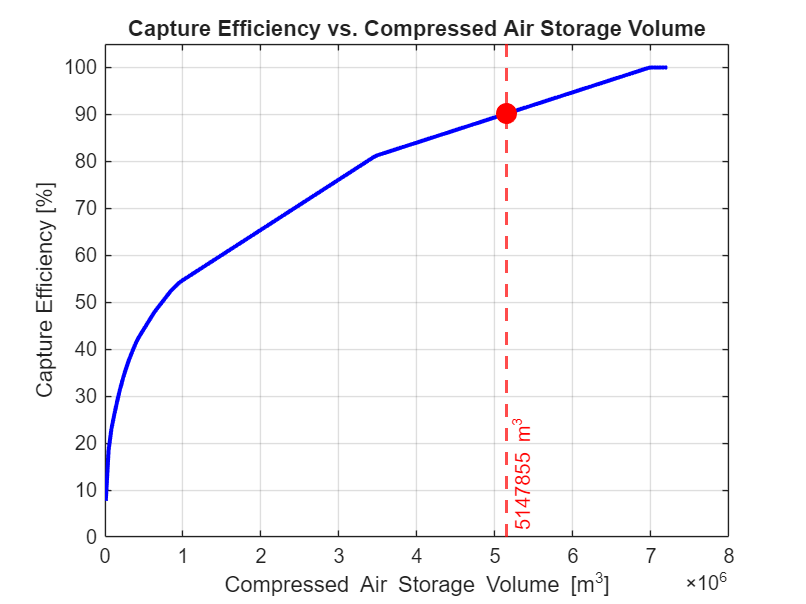


%% 7. Plotting
% Convert energy axis to gas volume [m^3]
V_gas_range = V_max_range * MWh_to_m3;  % [m^3]

% --- Figure 1: Capture Efficiency vs. Gas Volume ---
figure('Position', [100, 100, 800, 600], 'Color', 'w');
plot(V_gas_range, eta_capture, 'b-', 'LineWidth', 2);
hold on;
if ~isnan(V_knee)
    xline(V_knee_m3, 'r--', sprintf('%.0f m^3', V_knee_m3), ...
        'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right', ...
        'LabelVerticalAlignment', 'bottom');
    plot(V_knee_m3, eta_capture(idx_knee), 'ro', 'MarkerSize', 10, ...
        'MarkerFaceColor', 'r');
end
xlabel('Compressed Air Storage Volume [m^3]');
ylabel('Capture Efficiency [%]');
title('Capture Efficiency vs. Compressed Air Storage Volume');
grid on;
ylim([0 105]);

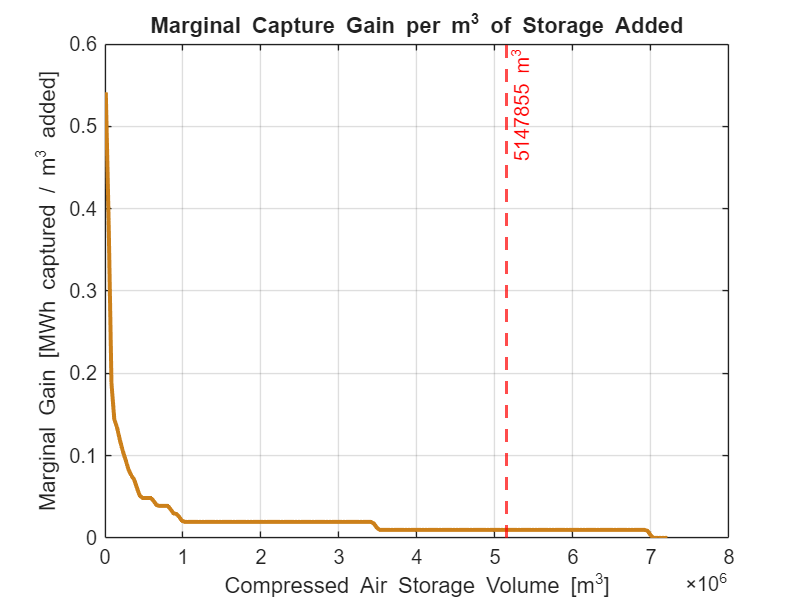


% --- Figure 2: Marginal Gain vs. Gas Volume ---
% Recompute marginal gain w.r.t. volume: dE_captured / dV_gas
marginal_gain_vol = gradient(E_captured, V_gas_range);  % [MWh / m^3]

figure('Position', [150, 150, 800, 600], 'Color', 'w');
plot(V_gas_range, marginal_gain_vol, 'Color', [0.8 0.5 0.1], 'LineWidth', 2);
hold on;
if ~isnan(V_knee)
    xline(V_knee_m3, 'r--', sprintf('%.0f m^3', V_knee_m3), ...
        'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right');
end
xlabel('Compressed Air Storage Volume [m^3]');
ylabel('Marginal Gain [MWh captured / m^3 added]');
title('Marginal Capture Gain per m^3 of Storage Added');
grid on;


%% 8. Summary Table
fprintf('\n====================== Summary Table ======================\n');


====================== Summary Table ======================


fprintf('%-14s  %-14s  %-12s  %-12s  %-12s\n', ...
    'V_max [MWh]', 'V_gas [m^3]', 'E_captured', 'Capture[%]', 'Time Full[%]');

V_max [MWh]     V_gas [m^3]     E_captured    Capture[%]    Time Full[%]


fprintf('%-14s  %-14s  %-12s  %-12s  %-12s\n', ...
    '', '', '[GWh]', '', '');

                                [GWh]                                   


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------



V_print = [500, 1000, 2500, 5000, 10000, 15000, 20000, 30000, 50000];
for v = V_print
    [~, idx] = min(abs(V_max_range - v));
    fprintf('%-14.0f  %-14.0f  %-12.2f  %-12.1f  %-12.1f\n', ...
        V_max_range(idx), V_gas_range(idx), E_captured(idx)/1e3, ...
        eta_capture(idx), time_full_pct(idx));
end

451             46480           33.55         18.5          13.5        
1154            118840          47.18         26.0          11.5        
2559            263560          64.52         35.6          10.0        
5018            516820          81.19         44.8          9.0         
9935            1023339         99.66         55.0          7.3         
14853           1529859         109.50        60.4          6.4         
20122           2072558         120.03        66.2          5.5         
29957           3085597         139.70        77.1          3.4         
49978           5147855         163.45        90.2          1.4         


fprintf('%s\n', repmat('=', 1, 70));

%% I-CAES Feasibility Analysis with Thermal Energy Storage
%  Comprehensive time-domain simulation of an Isothermal Compressed Air
%  Energy Storage system with TES heat recovery and thermal decay.
%
%  Input:  Team38_net_produce.csv (Time_s, Net_Produce_MW)
%  Output: 6 diagnostic figures + console summary
%
%  System Parameters from parameter_determination_gemini.pdf:
%    aSupply    = 0.047  (supply transport losses)
%    aInjection = 0.193  (compression losses)
%    bStorage   = 6.27e-8 s^-1 (TES thermal decay)
%    aExtraction= 0.178  (expansion losses @ full TES)
%    aDemand    = 0.020  (demand transport losses)
%    Theoretical RTE = 61.9% (ignoring storage time)
% ---------------------------------------------------------------

clear; clc; close all;

%% 1. Data Import
data = readtable('Team38_net_produce.csv');
time_s = data{:, 1};          % Time [s]
P_net  = data{:, 2};          % Net produce [MW] (supply - demand)
N      = length(P_net);
dt_s   = 900;                  % Timestep [s]
dt_h   = dt_s / 3600;         % Timestep [hours]

%% 2. System Parameters
% --- Loss coefficients (from PDF) ---
a_supply    = 0.047;   % Supply transport dissipation
a_injection = 0.193;   % Injection (compression) dissipation
b_storage   = 6.27e-8; % TES decay constant [s^-1]
a_extraction= 0.178;   % Extraction (expansion) dissipation at FULL TES
a_demand    = 0.020;   % Demand transport dissipation

% --- Physical constants ---
gamma  = 1.4;          % Ratio of specific heats (air)
R_air  = 287;          % Gas constant for air [J/(kg*K)]
c_p    = 1005;         % Specific heat at constant pressure [J/(kg*K)]
T_amb  = 300;          % Ambient temperature [K]
P_store_Pa = 80e5;     % Storage pressure [Pa] (80 bar)
P_atm_Pa   = 101325;   % Atmospheric pressure [Pa]

% --- Compression thermodynamics ---
% Near-isothermal compression with polytropic index n ~ 1.05
% Due to spray cooling, the exit temperature is above ambient
n_poly = 1.05;         % Polytropic index (1.0 = perfect isothermal, 1.4 = adiabatic)
T_hot  = T_amb * (P_store_Pa / P_atm_Pa)^((n_poly - 1) / n_poly);
fprintf('Compression exit temperature (polytropic n=%.2f): %.1f K (%.1f C)\n', ...
    n_poly, T_hot, T_hot - 273.15);

Compression exit temperature (polytropic n=1.05): 369.4 K (96.2 C)



% TES temperature boost ratio: determines how much more work you get
% with TES heat vs. environment-only expansion
boost_ratio = T_hot / T_amb;
fprintf('TES temperature boost ratio: %.3f (%.1f%% more work with TES)\n', ...
    boost_ratio, (boost_ratio - 1) * 100);

TES temperature boost ratio: 1.231 (23.1% more work with TES)



% --- Charging power limit ---
P_charge_max = 300;    % [MW] max charging power

% --- Air storage (cavern) ---
% 6.8 Mm^3 at 80 bar, using E = P_store * V * ln(P_store/P_atm)
V_cavern = 6.8e6;     % [m^3]
E_cavern_max_J = P_store_Pa * V_cavern * log(P_store_Pa / P_atm_Pa);
E_cavern_max = E_cavern_max_J / 3.6e9;  % Convert J -> MWh
fprintf('Cavern max energy capacity: %.0f MWh (%.1f GWh)\n', ...
    E_cavern_max, E_cavern_max / 1e3);

Cavern max energy capacity: 66018 MWh (66.0 GWh)



% --- TES decay per timestep ---
TES_retention = exp(-b_storage * dt_s);  % Per-step retention factor
fprintf('TES retention per 15-min step: %.6f\n', TES_retention);

TES retention per 15-min step: 0.999944


fprintf('TES retention per day: %.4f (%.2f%% loss/day)\n', ...
    TES_retention^(96), (1 - TES_retention^96)*100);

TES retention per day: 0.9946 (0.54% loss/day)



%% 3. Time-Domain Simulation
% State variables
E_air    = 0;              % Compressed air SOC [MWh]
Q_TES    = 0;              % Thermal energy in TES [MWh]

% Time-series tracking arrays
E_air_ts      = zeros(N, 1);    % Air SOC over time
Q_TES_ts      = zeros(N, 1);    % TES energy over time
Q_produced_ts = zeros(N, 1);    % Thermal energy produced per step
Q_consumed_ts = zeros(N, 1);    % Thermal energy consumed per step
Q_decay_ts    = zeros(N, 1);    % Thermal energy lost to decay per step
P_discharge_ts= zeros(N, 1);    % Actual discharge power delivered [MW]
P_demand_ts   = zeros(N, 1);    % Power deficit (what grid needs) [MW]
P_charge_ts   = zeros(N, 1);    % Actual charging power [MW]
E_in_total    = 0;              % Cumulative electrical energy input [MWh]
E_out_total   = 0;              % Cumulative electrical energy output [MWh]
E_unmet_total = 0;              % Cumulative unmet demand [MWh]

for t = 1:N
    % ---- TES decay (every timestep, regardless of charge/discharge) ----
    Q_before_decay = Q_TES;
    Q_TES = Q_TES * TES_retention;
    Q_decay_ts(t) = Q_before_decay - Q_TES;
    
    if P_net(t) > 0
        % ============== SURPLUS: CHARGE ==============
        % Cap charging power
        P_charge = min(P_net(t), P_charge_max);
        
        % Stage 1: Supply transport losses
        P_after_supply = P_charge * (1 - a_supply);
        
        % Stage 2: Injection (compression) — energy goes to air + heat
        E_air_in = P_after_supply * (1 - a_injection) * dt_h;  % [MWh] to air
        
        % Check cavern capacity
        E_room = E_cavern_max - E_air;
        E_air_actual = min(E_air_in, E_room);
        
        % Update air SOC
        E_air = E_air + E_air_actual;
        
        % Thermal energy produced during compression
        % For near-isothermal compression: Q = W_compression (first law, dU~0)
        % The heat is at T_hot and captured by TES
        % Thermal energy per unit of air stored = 1:1 (isothermal: Q = W)
        Q_produced = E_air_actual;  % [MWh] of thermal energy to TES
        Q_TES = Q_TES + Q_produced;
        
        % Track
        P_charge_ts(t) = P_charge;
        Q_produced_ts(t) = Q_produced;
        E_in_total = E_in_total + P_charge * dt_h;
        
    elseif P_net(t) < 0
        % ============== DEFICIT: DISCHARGE ==============
        P_deficit = abs(P_net(t));  % Power needed from storage [MW]
        P_demand_ts(t) = P_deficit;
        
        % Determine achievable discharge power based on TES availability
        % With full TES: isothermal expansion at T_hot
        %   P_out = E_air_rate * (1-a_extraction) * (1-a_demand) * boost
        % Without TES: isothermal expansion at T_amb (environment heat only)
        %   P_out = E_air_rate * (1-a_extraction) * (1-a_demand) * 1.0
        % The boost factor from TES: T_hot/T_amb
        %
        % To deliver P_deficit MW to grid, we need to release air energy:
        %   At full TES:  E_air_rate = P_deficit / ((1-a_extract)*(1-a_demand)*boost)
        %   At no TES:    E_air_rate = P_deficit / ((1-a_extract)*(1-a_demand)*1.0)
        
        eta_extract_base = (1 - a_extraction) * (1 - a_demand);  % ~0.805
        
        % Maximum air energy rate we can release this step [MW equivalent]
        E_air_available_rate = E_air / dt_h;  % Max rate from air [MW]
        
        % Thermal energy needed for full-boost isothermal expansion
        % Q_needed = E_air_released (1:1 ratio for isothermal)
        
        % Calculate how much TES we have relative to air
        Q_TES_available_rate = Q_TES / dt_h;  % Max TES power [MW]
        
        % Try to meet the full deficit with best available efficiency
        % First, calculate required air release rate at full boost
        E_air_rate_fullboost = P_deficit / (eta_extract_base * boost_ratio);
        Q_needed_fullboost = E_air_rate_fullboost * dt_h;  % TES heat needed [MWh]
        
        % Calculate required air release rate at no boost (env only)
        E_air_rate_noboost = P_deficit / eta_extract_base;
        
        if E_air_rate_fullboost * dt_h <= E_air && Q_needed_fullboost <= Q_TES
            % Case 1: Enough air AND enough TES → full boost discharge
            E_air_released = E_air_rate_fullboost * dt_h;
            Q_consumed = E_air_released;  % 1:1 thermal ratio
            P_delivered = P_deficit;  % Full demand met
            
        elseif E_air_rate_noboost * dt_h <= E_air
            % Case 2: Enough air but not enough TES → partial/no boost
            % Use whatever TES is available, supplement with environment
            E_air_released_try = E_air_rate_fullboost * dt_h;
            
            if Q_TES > 0
                % Partial TES: interpolate between boost and no-boost
                % Use all available TES
                Q_consumed = min(Q_TES, E_air_rate_noboost * dt_h);
                % Fraction of thermal need met by TES
                frac_TES = Q_consumed / (E_air_rate_noboost * dt_h);
                % Effective boost: interpolate between 1.0 and boost_ratio
                eff_boost = 1.0 + frac_TES * (boost_ratio - 1.0);
                % Air needed to deliver P_deficit with this effective boost
                E_air_rate_eff = P_deficit / (eta_extract_base * eff_boost);
                
                if E_air_rate_eff * dt_h <= E_air
                    E_air_released = E_air_rate_eff * dt_h;
                    P_delivered = P_deficit;
                else
                    % Not quite enough air even with partial boost
                    E_air_released = E_air;
                    eff_boost_actual = 1.0 + (Q_consumed / E_air) * (boost_ratio - 1.0);
                    P_delivered = (E_air / dt_h) * eta_extract_base * eff_boost_actual;
                    Q_consumed = min(Q_TES, E_air);
                end
            else
                % No TES at all: environment only (boost = 1.0)
                if E_air_rate_noboost * dt_h <= E_air
                    E_air_released = E_air_rate_noboost * dt_h;
                    P_delivered = P_deficit;
                    Q_consumed = 0;
                else
                    E_air_released = E_air;
                    P_delivered = (E_air / dt_h) * eta_extract_base;
                    Q_consumed = 0;
                end
            end
        else
            % Case 3: Not enough air → deliver whatever we can
            E_air_released = E_air;
            Q_consumed = min(Q_TES, E_air);
            frac_TES = Q_consumed / max(E_air, 1e-10);
            eff_boost = 1.0 + min(frac_TES, 1.0) * (boost_ratio - 1.0);
            P_delivered = (E_air / dt_h) * eta_extract_base * eff_boost;
            
        end
        
        % Update state
        E_air = E_air - E_air_released;
        Q_TES = Q_TES - Q_consumed;
        
        % Ensure non-negative
        E_air = max(E_air, 0);
        Q_TES = max(Q_TES, 0);
        
        % Track
        P_discharge_ts(t) = P_delivered;
        Q_consumed_ts(t) = Q_consumed;
        E_out_total = E_out_total + P_delivered * dt_h;
        E_unmet = max(P_deficit - P_delivered, 0) * dt_h;
        E_unmet_total = E_unmet_total + E_unmet;
    end
    
    % Store time-series
    E_air_ts(t) = E_air;
    Q_TES_ts(t) = Q_TES;
end

%% 4. Compute Summary Statistics
time_days = time_s / 86400;

Q_produced_total = sum(Q_produced_ts);
Q_consumed_total = sum(Q_consumed_ts);
Q_decay_total    = sum(Q_decay_ts);
Q_TES_peak       = max(Q_TES_ts);

E_demand_total = sum(P_demand_ts) * dt_h;  % Total energy demand from storage
RTE = E_out_total / max(E_in_total, 1e-10) * 100;

fprintf('\n========== I-CAES SIMULATION RESULTS ==========\n');


========== I-CAES SIMULATION RESULTS ==========


fprintf('--- Energy Summary ---\n');

--- Energy Summary ---


fprintf('Total electrical energy IN (charging):  %.0f MWh (%.1f GWh)\n', ...
    E_in_total, E_in_total/1e3);

Total electrical energy IN (charging):  181270 MWh (181.3 GWh)


fprintf('Total electrical energy OUT (discharge): %.0f MWh (%.1f GWh)\n', ...
    E_out_total, E_out_total/1e3);

Total electrical energy OUT (discharge): 117435 MWh (117.4 GWh)


fprintf('Round-Trip Efficiency: %.1f%%\n', RTE);

Round-Trip Efficiency: 64.8%


fprintf('\n--- Thermal Energy (TES) ---\n');


--- Thermal Energy (TES) ---


fprintf('Total thermal energy PRODUCED: %.0f MWh (%.1f GWh)\n', ...
    Q_produced_total, Q_produced_total/1e3);

Total thermal energy PRODUCED: 139410 MWh (139.4 GWh)


fprintf('Total thermal energy CONSUMED: %.0f MWh (%.1f GWh)\n', ...
    Q_consumed_total, Q_consumed_total/1e3);

Total thermal energy CONSUMED: 105299 MWh (105.3 GWh)


fprintf('Total thermal energy LOST (decay): %.0f MWh (%.1f GWh)\n', ...
    Q_decay_total, Q_decay_total/1e3);

Total thermal energy LOST (decay): 18223 MWh (18.2 GWh)


fprintf('Peak TES level: %.0f MWh → TES tank must hold at least this\n', Q_TES_peak);

Peak TES level: 43128 MWh → TES tank must hold at least this


fprintf('TES remaining at end of year: %.0f MWh\n', Q_TES);

TES remaining at end of year: 15888 MWh


fprintf('\n--- Demand Coverage ---\n');


--- Demand Coverage ---


fprintf('Total demand from storage: %.0f MWh\n', E_demand_total);

Total demand from storage: 139677 MWh


fprintf('Total demand MET: %.0f MWh (%.1f%%)\n', ...
    E_out_total, E_out_total / max(E_demand_total, 1e-10) * 100);

Total demand MET: 117435 MWh (84.1%)


fprintf('Total demand UNMET: %.0f MWh\n', E_unmet_total);

Total demand UNMET: 22242 MWh


fprintf('\n--- Discharge Power ---\n');


--- Discharge Power ---


discharge_events = P_discharge_ts > 0;
if any(discharge_events)
    fprintf('Max discharge power delivered: %.1f MW\n', max(P_discharge_ts));
    fprintf('Avg discharge power (when active): %.1f MW\n', ...
        mean(P_discharge_ts(discharge_events)));
end

Max discharge power delivered: 64.0 MW


Avg discharge power (when active): 21.3 MW


fprintf('\n--- Storage Sizing ---\n');


--- Storage Sizing ---


fprintf('Air cavern volume: %.1f Mm^3\n', V_cavern / 1e6);

Air cavern volume: 6.8 Mm^3


fprintf('Air cavern energy capacity: %.0f MWh\n', E_cavern_max);

Air cavern energy capacity: 66018 MWh


fprintf('Peak air SOC: %.0f MWh (%.1f%% of capacity)\n', ...
    max(E_air_ts), max(E_air_ts) / E_cavern_max * 100);

Peak air SOC: 47002 MWh (71.2% of capacity)


fprintf('Required TES capacity: %.0f MWh\n', Q_TES_peak);

Required TES capacity: 43128 MWh


fprintf('==============================================\n');

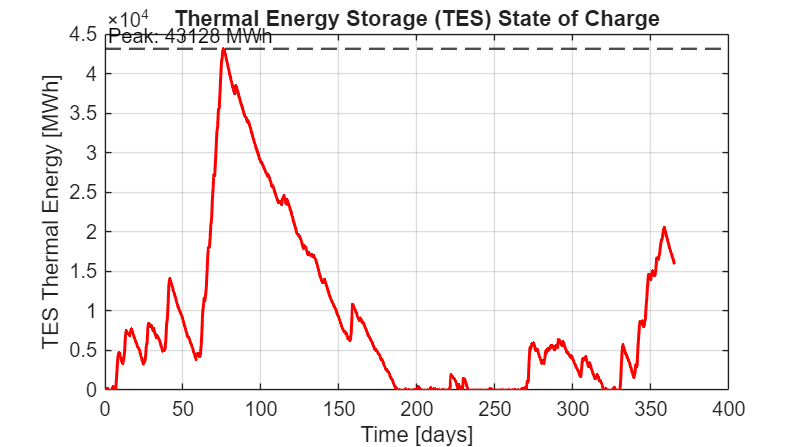


%% 5. Plotting

% Convert CAES energy to gas volume for reference
MWh_to_m3 = 3.6e9 / (P_store_Pa * log(P_store_Pa / P_atm_Pa));

% --- Figure 1: TES Thermal Energy vs. Time ---
figure('Position', [50, 50, 900, 500], 'Color', 'w');
plot(time_days, Q_TES_ts, 'r-', 'LineWidth', 1.5);
hold on;
yline(Q_TES_peak, 'k--', sprintf('Peak: %.0f MWh', Q_TES_peak), ...
    'LineWidth', 1.2, 'LabelHorizontalAlignment', 'left');
xlabel('Time [days]');
ylabel('TES Thermal Energy [MWh]');
title('Thermal Energy Storage (TES) State of Charge');
grid on;

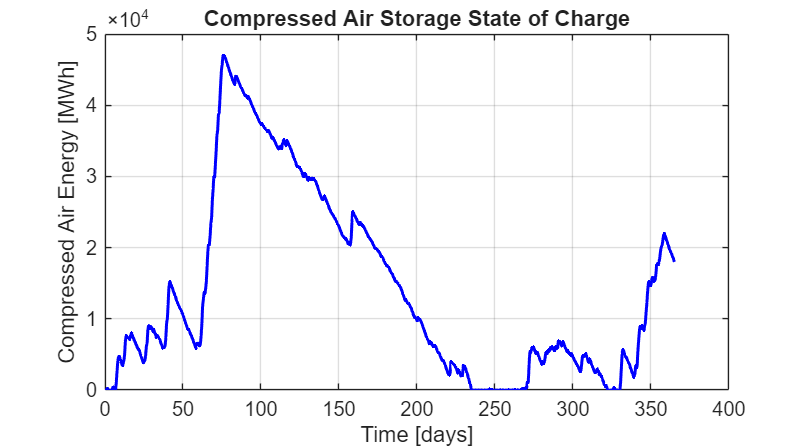


% --- Figure 2: Air SOC vs. Time ---
figure('Position', [100, 100, 900, 500], 'Color', 'w');
plot(time_days, E_air_ts, 'b-', 'LineWidth', 1.5);
hold on;

xlabel('Time [days]');
ylabel('Compressed Air Energy [MWh]');
title('Compressed Air Storage State of Charge');
grid on;

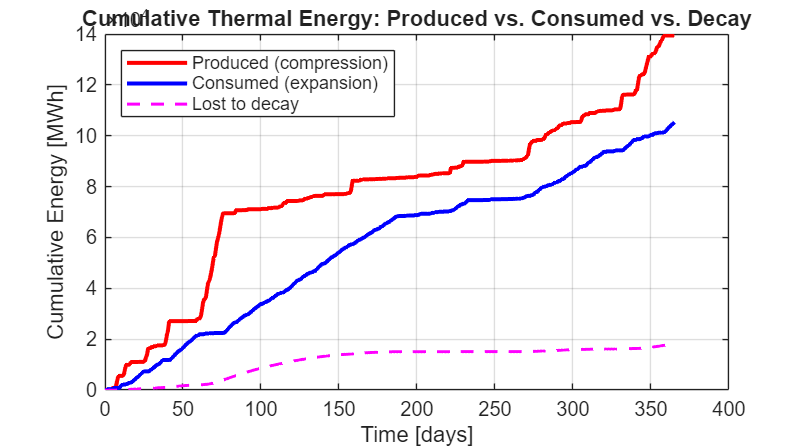


% --- Figure 3: Thermal Produced vs. Consumed ---
figure('Position', [150, 150, 900, 500], 'Color', 'w');
cum_produced = cumsum(Q_produced_ts);
cum_consumed = cumsum(Q_consumed_ts);
cum_decay    = cumsum(Q_decay_ts);
plot(time_days, cum_produced, 'r-', 'LineWidth', 2); hold on;
plot(time_days, cum_consumed, 'b-', 'LineWidth', 2);
plot(time_days, cum_decay, 'm--', 'LineWidth', 1.5);
xlabel('Time [days]');
ylabel('Cumulative Energy [MWh]');
title('Cumulative Thermal Energy: Produced vs. Consumed vs. Decay');
legend('Produced (compression)', 'Consumed (expansion)', 'Lost to decay', ...
    'Location', 'northwest');
grid on;

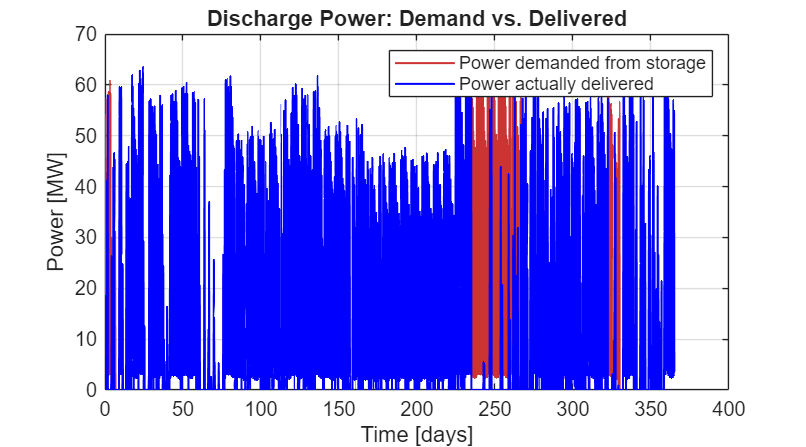


% --- Figure 4: Discharge Power Achieved ---
figure('Position', [200, 200, 900, 500], 'Color', 'w');
plot(time_days, P_demand_ts, 'Color', [0.8 0.2 0.2 0.3], 'LineWidth', 1); hold on;
plot(time_days, P_discharge_ts, 'b-', 'LineWidth', 1);
xlabel('Time [days]');
ylabel('Power [MW]');
title('Discharge Power: Demand vs. Delivered');
legend('Power demanded from storage', 'Power actually delivered', ...
    'Location', 'northeast');
grid on;

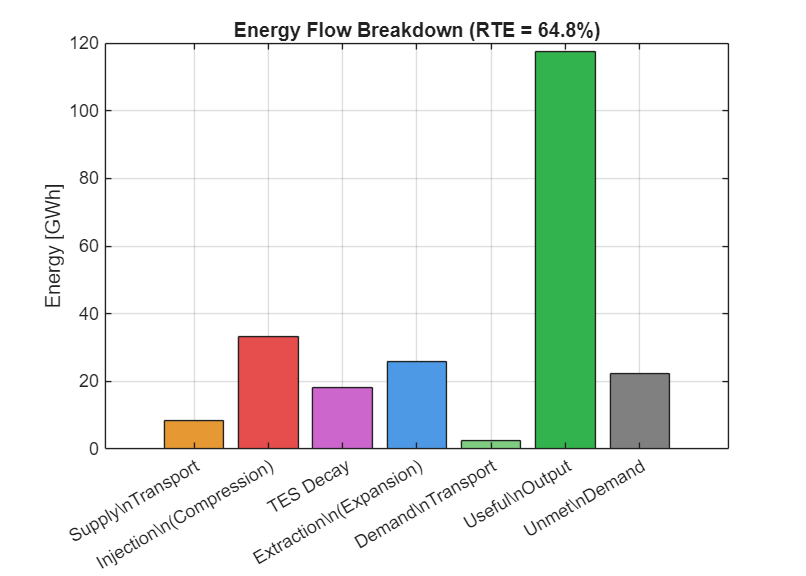


% --- Figure 5: Round-Trip Efficiency Breakdown ---
figure('Position', [250, 250, 700, 500], 'Color', 'w');

% Calculate loss breakdown
loss_supply = E_in_total * a_supply;
loss_injection = (E_in_total * (1-a_supply)) * a_injection;
E_after_inject = E_in_total * (1-a_supply) * (1-a_injection);
loss_decay_pct = Q_decay_total;
loss_extraction_equiv = E_out_total / (1-a_demand) / (1-a_extraction) * a_extraction;
loss_demand = E_out_total / (1-a_demand) * a_demand;
E_useful = E_out_total;
E_unmet_bar = E_unmet_total;

categories = {'Supply\nTransport', 'Injection\n(Compression)', ...
    'TES Decay', 'Extraction\n(Expansion)', 'Demand\nTransport', ...
    'Useful\nOutput', 'Unmet\nDemand'};
values = [loss_supply, loss_injection, loss_decay_pct, ...
    loss_extraction_equiv, loss_demand, E_useful, E_unmet_bar];
colors = [0.9 0.6 0.2; 0.9 0.3 0.3; 0.8 0.4 0.8; 0.3 0.6 0.9; ...
    0.5 0.8 0.5; 0.2 0.7 0.3; 0.5 0.5 0.5];

b = bar(values / 1e3, 'FaceColor', 'flat');
for k = 1:length(values)
    b.CData(k,:) = colors(k,:);
end
set(gca, 'XTickLabel', categories, 'FontSize', 9);
ylabel('Energy [GWh]');
title(sprintf('Energy Flow Breakdown (RTE = %.1f%%)', RTE));
grid on;

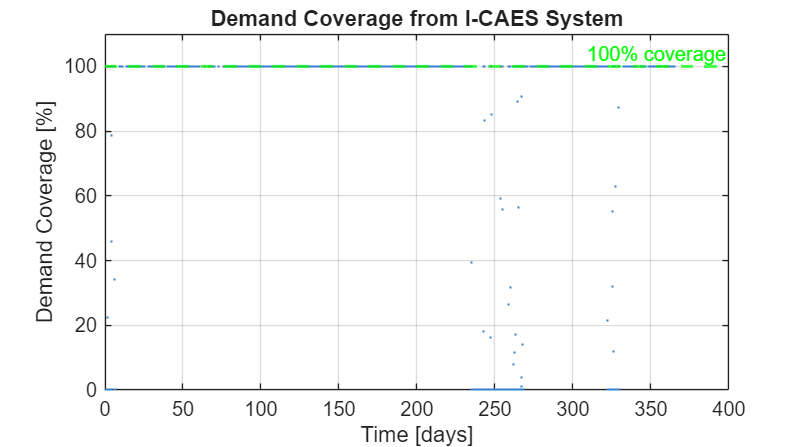


% --- Figure 6: Demand Coverage Over Time ---
figure('Position', [300, 300, 900, 500], 'Color', 'w');
coverage_pct = zeros(N, 1);
for t = 1:N
    if P_demand_ts(t) > 0
        coverage_pct(t) = P_discharge_ts(t) / P_demand_ts(t) * 100;
    else
        coverage_pct(t) = NaN;  % No demand this step
    end
end
plot(time_days, coverage_pct, '.', 'MarkerSize', 2, 'Color', [0.2 0.5 0.8]);
xlabel('Time [days]');
ylabel('Demand Coverage [%]');
title('Demand Coverage from I-CAES System');
ylim([0 110]);
grid on;
yline(100, 'g--', '100% coverage', 'LineWidth', 1.5);